syms a1 a2 a3 a4 a5 a6 a7 a8 b1 b2 b3 w1 w2 w3 w4 w5

A = [a1 a2 a3 0;
     0 a4 a5 w1;
     a6 a7 a8 0;
     0 w2 w3 w4];
B = [b1; b2; b3; w5];

X = simplify(A \ B,'IgnoreAnalyticConstraints',true)

$$X = \begin{array}{l} \left(\begin{array}{c} \frac{a_{2}\,a_{8}\,w_{1}\,w_{5}-a_{3}\,a_{7}\,w_{1}\,w_{5}-a_{2}\,b_{3}\,w_{1}\,w_{3}+a_{3}\,b_{3}\,w_{1}\,w_{2}+a_{7}\,b_{1}\,w_{1}\,w_{3}-a_{8}\,b_{1}\,w_{1}\,w_{2}+a_{2}\,a_{5}\,b_{3}\,w_{4}-a_{3}\,a_{4}\,b_{3}\,w_{4}-a_{2}\,a_{8}\,b_{2}\,w_{4}+a_{3}\,a_{7}\,b_{2}\,w_{4}+a_{4}\,a_{8}\,b_{1}\,w_{4}-a_{5}\,a_{7}\,b_{1}\,w_{4}}{\sigma_{1}}\\ -\frac{a_{1}\,a_{8}\,w_{1}\,w_{5}-a_{3}\,a_{6}\,w_{1}\,w_{5}-a_{1}\,b_{3}\,w_{1}\,w_{3}+a_{6}\,b_{1}\,w_{1}\,w_{3}+a_{1}\,a_{5}\,b_{3}\,w_{4}-a_{1}\,a_{8}\,b_{2}\,w_{4}+a_{3}\,a_{6}\,b_{2}\,w_{4}-a_{5}\,a_{6}\,b_{1}\,w_{4}}{\sigma_{1}}\\ \frac{a_{1}\,a_{7}\,w_{1}\,w_{5}-a_{2}\,a_{6}\,w_{1}\,w_{5}-a_{1}\,b_{3}\,w_{1}\,w_{2}+a_{6}\,b_{1}\,w_{1}\,w_{2}+a_{1}\,a_{4}\,b_{3}\,w_{4}-a_{1}\,a_{7}\,b_{2}\,w_{4}+a_{2}\,a_{6}\,b_{2}\,w_{4}-a_{4}\,a_{6}\,b_{1}\,w_{4}}{\sigma_{1}}\\ \frac{a_{1}\,a_{4}\,a_{8}\,w_{5}-a_{1}\,a_{5}\,a_{7}\,w_{5}+a_{2}\,a_{5}\,a_{6}\,w_{5}-a_{3}\,a_{4}\,a_{6}\,w_{5}-a_{1}\,a_{4}\,b_{3}\,w_{3}+a_{1}\,a_{5}\,b_{3}\,w_{2}+a_{1}\,a_{7}\,b_{2}\,w_{3}-a_{1}\,a_{8}\,b_{2}\,w_{2}-a_{2}\,a_{6}\,b_{2}\,w_{3}+a_{3}\,a_{6}\,b_{2}\,w_{2}+a_{4}\,a_{6}\,b_{1}\,w_{3}-a_{5}\,a_{6}\,b_{1}\,w_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{1}\,a_{7}\,w_{1}\,w_{3}-a_{1}\,a_{8}\,w_{1}\,w_{2}-a_{2}\,a_{6}\,w_{1}\,w_{3}+a_{3}\,a_{6}\,w_{1}\,w_{2}+a_{1}\,a_{4}\,a_{8}\,w_{4}-a_{1}\,a_{5}\,a_{7}\,w_{4}+a_{2}\,a_{5}\,a_{6}\,w_{4}-a_{3}\,a_{4}\,a_{6}\,w_{4} \end{array}$$

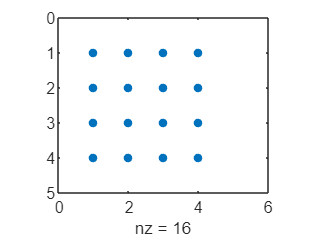


C = [0 0 0 1];
spy(jacobian(C/A,[w1;w2;w3;w4;w5]))